# **batch_run_pca_temporal**

run PCA on segmented SPA EEG data, implementing ERP appropriate PCA

author: Gerardo Parra, last updated: 2023-02-21

eeglab: options file is C:\Users\ch220650\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
EEGLAB: adding "FASTER" v.1.0 (see >> help eegplugin_FASTER)
EEGLAB: adding "MARA-master" v? (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.3 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "bvaio" v1.57 (see >> help eegplugin_bva_io)
EEGLAB: adding "dipfit" v2.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "fieldtrip-" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "firfilt" v1.6.2 (see >> help eegplugin_firfilt)
EEGLAB: adding "tmullen-cleanline-696a7181b7d" v0 (see >> help eegplugin_cleanline)


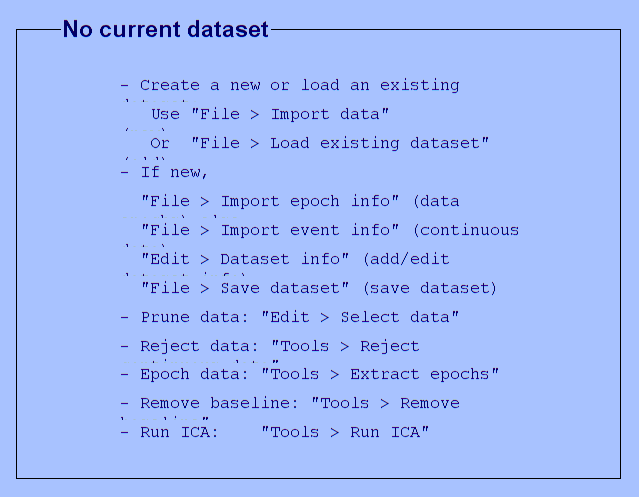

eeglab; clear

## inputs

### loading data

task      = get_task('ath'); 
path.tag  = '_seg_.1_30_200msblcorr';
path.eeg  = fullfile( 'Z:','Groups','SPA','01_Data_Raw_Summary_Processed',  ...
                       'EEG','Participant_Data','03_Processed_Data' );
path.task = fullfile( path.eeg,task.path );
path.grps = fullfile( path.eeg,'01_Subject_Info_For_Processing', ...
                      'Group_Assignments.mat' );
group     = struct('name',{'TD','ASD','SPD'});

### processing params

P.chan.incl = 1:129; %[load_1020_chans() 29 35 110 111]; %load_1020_chans(); %
P.chan.excl_1020 = [9 17 22 33 45 58 70 75 83 96 108];
P.chan.excl_all  = [1 125 8 14 126 127 21 25 32 128 38   ...
                    43 48 44 49 56 57 63 64 68 69 73 74  ...
                    81 82 88 89 94 95 99 100 107 113 114 ...
               120 119 121 129];
%P.chan.excl_all = [129]

P = struct with fields:
    chan: [1×1 struct]


P.chan.excl = [P.chan.excl_all]; %[P.chan.excl_1020 P.chan.excl_all] %
P.chan.pca  = setdiff(P.chan.incl,P.chan.excl); % channels to run PCA on
P.chan.plot = [36];       % channels to base plots on
P.t.win     = [-50 750];  % time window (ms) to use in PCA, [] to use all
P.t.rsamp   = 1;         % factor to resample time series by
P.pca.by_group = false;  % 1 = run separate PCAs by group, 0 = single PCA
P.pca.grand_avg = false; % 1 = average over all conditons and participants

## load data

[DATA,FPI,P.t.times,P.t.seg_win,P.t.Fs] = load_eeg_into_struct(path);

### create observation matrices

EEG = struct('data',[],'mean',[],'n',[]);
if P.pca.by_group
    n.group = max([DATA.group]);
    for i_g = 1:n.group
        % create 4d matrix: channels x samples x conditions x subjects
        EEG(i_g).ids = find([DATA.group]==i_g);
        A = cat(4,DATA(EEG(i_g).ids).eeg);
        EEG(i_g).mean = squeeze(mean(A,4));
        EEG(i_g).n = size(A,4); EEG(i_g).group = group.name{i_g};
        % prep for pca: samples x channels x subjects x conditions
        EEG(i_g).data = permute(A,[2 1 4 3]); clear A
        if P.pca.grand_avg
        EEG(i_g).data = nanmean(EEG.data,3); EEG(i_g).n = 1;
        end
    end
else
    % create 4d matrix: channels x samples x conditions x subjects
    A = cat(4,DATA.eeg); EEG.mean = squeeze(mean(A,4)); EEG.n = size(A,4);
    EEG.ids = 1:EEG.n;
    % prep for pca: channels x samples x subjects x conditions
    EEG.data = permute(A,[1 2 4 3]); EEG.group = 'Grand'; clear A
         if P.pca.grand_avg
        EEG.data = nanmean(EEG.data,3); EEG.n = 1;
        end
end

for i_g = 1:length(group), group(i_g).ids = find([DATA.group]==i_g); end
n.group = size(EEG,2); n.chan = size(EEG(1).mean,1);
n.samp  = size(EEG(1).mean,2); n.cond = size(EEG(1).mean,3);

## run pca

### update PCA params

if    isempty(P.t.win), P.t.ind = 1:n.samp;
else, P.t.ind = get_time_win_idxs(P.t.win,P.t.seg_win*1000,P.t.Fs);
end
%update p.chan.pca to exclude bad channels
%P.chan.pca = setdiff(P.chan.pca,find(isnan(squeeze(EEG.data(:,1,:,1)))));

P.t.n = length(P.t.ind); P.t.plot = downsample(P.t.times(P.t.ind)*1000,P.t.rsamp);
n.rsamp = ceil(P.t.n/P.t.rsamp);
P.chan.n = length(P.chan.pca); P.chan.plot_i = P.chan.pca==P.chan.plot;
P.chan.locs = FPI.net_vstruct(P.chan.pca);

### spatial pca

for i_g = 1:n.group
    % get matrix, select time window
    A = EEG(i_g).data(P.chan.pca,P.t.ind,:,:);
    % reshape: observations x channels
    A = reshape(A,[P.chan.n P.t.n*EEG(i_g).n*n.cond])';
    % EKC
    [EKC.nF,EKC.L,EKC.refs] = myEKC(corr(A,'rows','complete'),size(A,1)); 
    EEG(i_g).ekc = EKC; 
    % run PCA
    EEG(i_g).pca = ep_doPCA( 'asis', 'Varimax', 0.01, 'SVD', 'COV',  ...
                             EEG(i_g).ekc.nF, A, 'C');
    clear EKC A
end

## Save the clusters of channels that pass .7 in fac pat for each factor

Deguire et. al 2022

for i_g = 1:n.group
    for i_f = 1: EEG(i_g).ekc.nF
    EEG(i_g).pca.clusters{i_f,1} = [P.chan.pca(find(EEG.pca.FacPat(:,i_f)>=.7))];
    end
end

### resort factor scores into individuals/groups

for i_g = 1:n.group    
    % reshape score: subjects x samples x conds x factor
    dims = [EEG(i_g).ekc.nF P.t.n EEG(i_g).n n.cond];
    score = EEG(i_g).pca.FacScr; score = reshape(score',dims);
    EEG(i_g).pca.FacScrPerm = permute(score,[3 2 4 1]); clear score
end

## plot outputs

### factor loadings and scores

fac_idx = 12

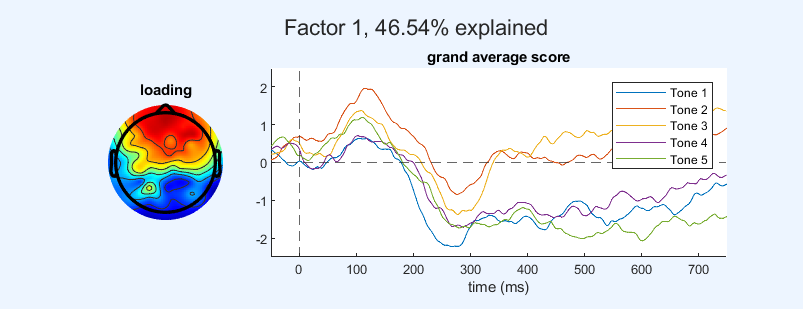

fac_idx = 12

fac_idx = 12

fac_idx = 12

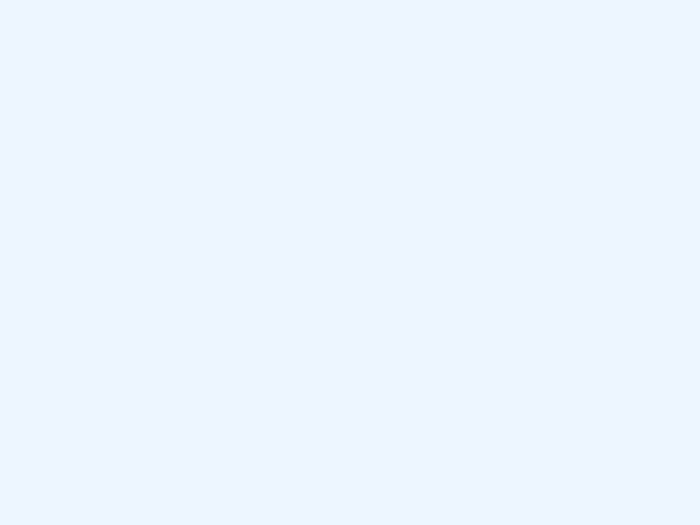

fac_idx = 24

fac_idx = 24

fac_idx = 24

fac_idx = 24

fac_idx = 61

fac_idx = 61

fac_idx = 61

fac_idx = 61

fac_idx = 22

fac_idx = 22

fac_idx = 22

fac_idx = 22

fac_idx = 42

fac_idx = 42

fac_idx = 42

fac_idx = 42

fac_idx = 38

fac_idx = 38

fac_idx = 38

fac_idx = 38

fac_idx = 85

fac_idx = 85

fac_idx = 85

fac_idx = 85

fac_idx = 87

fac_idx = 87

fac_idx = 87

fac_idx = 87

for i_g = 1:n.group
    for i_f = 1:EEG(i_g).ekc.nF
       % for sub_group_plot = 1:[n.group + length(group)]
             if ~P.pca.by_group && sub_group_plot >1
                sub_idxs = find([DATA.group] == sub_group_plot-1); tit = group(sub_group_plot-1).name;
            else
                sub_idxs = 1:length(DATA); tit = '';
             end
             fac_idx = find(EEG(i_g).pca.FacPat(:,i_f) == max(EEG(i_g).pca.FacPat(:,i_f)))
        figure('Position',[50 50 650 250]); hold on, ft = tiledlayout(1,4);
        title(ft,sprintf('Factor %d, %.2f%% explained',i_f,EEG(i_g).pca.facVar(i_f)*100))
        % plot factor loading (topography)
        nexttile([1 1]), hold on, title('loading')
        tp = topoplot(EEG(i_g).pca.FacPat(:,i_f),P.chan.locs); clear tp
        % plot mean factor score (timecourse)
        nexttile([1 3]), hold on, title('grand average score')
        plot(P.t.plot, squeeze(nanmean(EEG(i_g).pca.FacScrPerm(:,:,:,i_f),1)))
        xline(0,'--'), yline(0,'--'), legend(task.conds)
        xlim(P.t.win), ylim([-2.5 2.5]), xlabel('time (ms)')

       % end
    end
end

### selected factor score sums, for random individuals

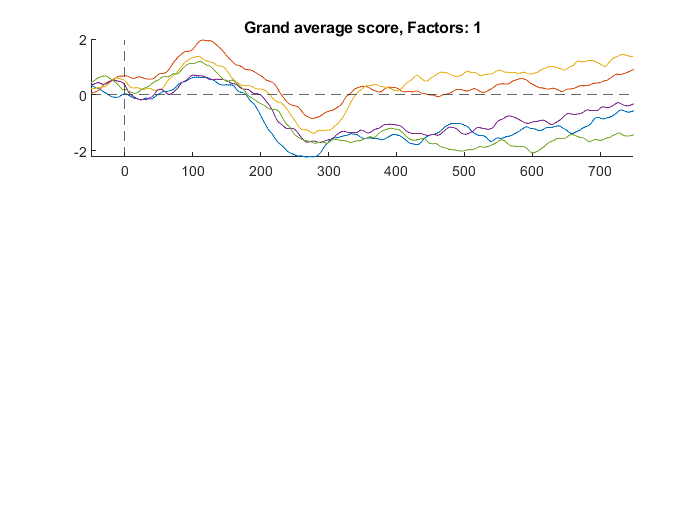

Error using linkaxes (line 74)
There must be at least one valid axes.

% select factors to plot summed scores for

P.pca.fac_ind = [3 ];
for i_g = 1:n.group
    figure; tiledlayout(3,3); nexttile([1 3]); hold on
    title([EEG(i_g).group ' average score, Factors: ' int2str(P.pca.fac_ind)])
    % plot grand average
    mean_fac_sum = mean(sum(EEG(i_g).pca.FacScrPerm(:,:,:,P.pca.fac_ind),4),1);
    plot( P.t.plot, squeeze(mean_fac_sum) )
    xlim(P.t.win), xline(0,'--'), yline(0,'--')
    % plot 6 random individuals
    P.randi = randsample(1:31,6); clear ft, ft = zeros(1,6);
if ~P.pca.grand_avg
    for i_r = P.randi
        nexttile([1 1]); ft(i_r) = gca; hold on
        title([int2str(DATA(i_r).id) ', ' group(DATA(i_r).group).name])
        subj_fac_sum = sum(EEG(i_g).pca.FacScrPerm(i_r,:,:,P.pca.fac_ind),4);
        plot( P.t.plot,squeeze(subj_fac_sum) )
        xlim(P.t.win), xline(0,'--'), yline(0,'--')
    end
end
    linkaxes(ft), clear mean_fac_sum subj_fac_sum
end

## selected factor scores sums, weighting orig data for random individuals

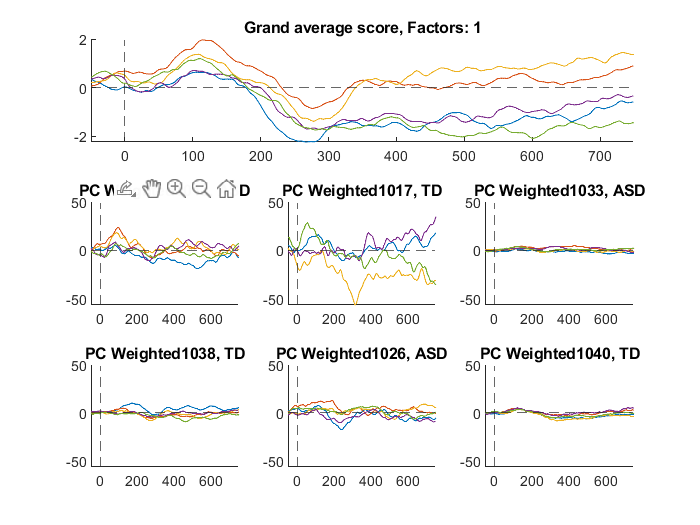

P.pca.fac_ind = 1;
FacPat_chan_idx = cell2mat(arrayfun(@(x) (find(P.chan.pca==x)),[EEG.pca.clusters{P.pca.fac_ind}],'UniformOutput',false));

for i_g = 1:n.group
    figure; tiledlayout(3,3); nexttile([1 3]); hold on
    title([EEG(i_g).group ' average score, Factors: ' int2str(P.pca.fac_ind)])
    % plot grand average
    mean_fac_sum = mean(sum(EEG(i_g).pca.FacScrPerm(:,:,:,P.pca.fac_ind),4),1);
    plot( P.t.plot, squeeze(mean_fac_sum) )
    xlim(P.t.win), xline(0,'--'), yline(0,'--')
    % plot 6 random individuals
    P.randi = randsample(1:31,6); clear ft, ft = zeros(1,6);
    for i_r = P.randi
        nexttile([1 1]); ft(i_r) = gca; hold on
        title(['PC Weighted' int2str(DATA(i_r).id) ', ' group(DATA(i_r).group).name])
        subj_fac_weighted = nanmean((DATA(i_r).eeg([EEG.pca.clusters{P.pca.fac_ind}],P.t.ind,:))./sum(EEG(i_g).pca.FacPat(FacPat_chan_idx,P.pca.fac_ind),2),1);
        plot( P.t.plot,squeeze(subj_fac_weighted) )
        xlim(P.t.win), xline(0,'--'), yline(0,'--')
    end

    linkaxes(ft), clear mean_fac_sum subj_fac_sum
end

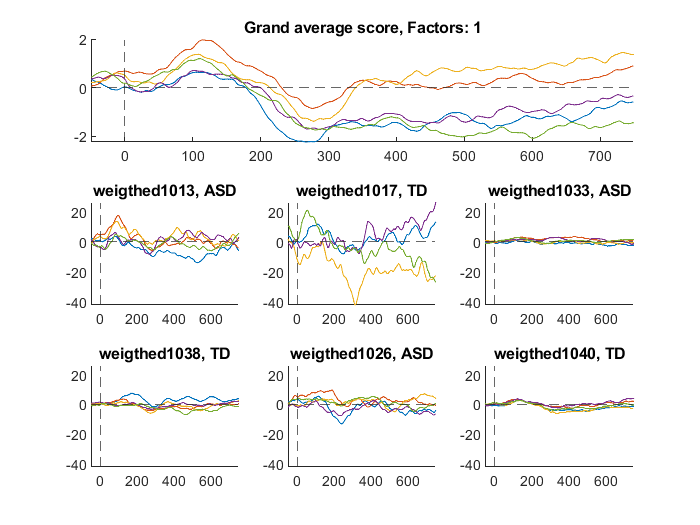

fr =      0     0     0     0     0     0


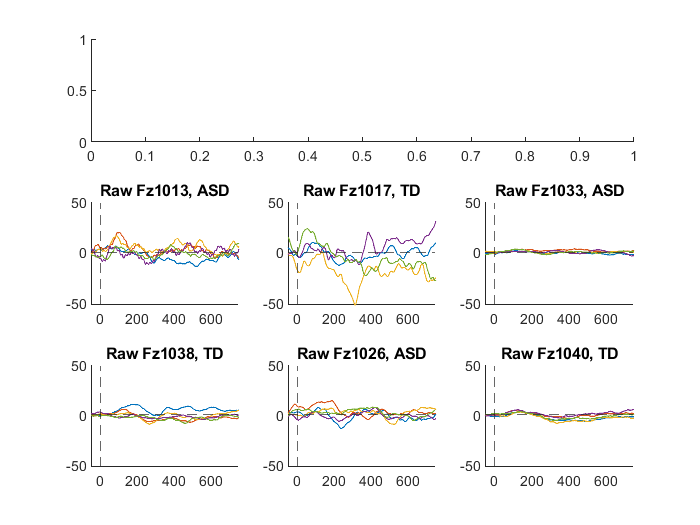

for i_g = 1:n.group
    figure; tiledlayout(3,3); nexttile([1 3]); hold on
    title([EEG(i_g).group ' average score, Factors: ' int2str(P.pca.fac_ind)])
    % plot grand average
    mean_fac_sum = mean(sum(EEG(i_g).pca.FacScrPerm(:,:,:,P.pca.fac_ind),4),1);
    plot( P.t.plot, squeeze(mean_fac_sum) )
    xlim(P.t.win), xline(0,'--'), yline(0,'--')
    % plot 6 random individuals
   % P.randi = randsample(1:31,6); clear ft, ft = zeros(1,6);
    for i_r = P.randi
        nexttile([1 1]); ft(i_r) = gca; hold on
        title(['weigthed' int2str(DATA(i_r).id) ', ' group(DATA(i_r).group).name])
        subj_fac_weighted = nanmean((DATA(i_r).eeg([EEG.pca.clusters{P.pca.fac_ind}],P.t.ind,:)).*sum(EEG(i_g).pca.FacPat(FacPat_chan_idx,P.pca.fac_ind),2),1);
               % subj_fac_weighted = nanmean((DATA(i_r).eeg([EEG.pca.clusters{P.pca.fac_ind}],P.t.ind,:)),1);

        plot( P.t.plot,squeeze(subj_fac_weighted) )
        xlim(P.t.win), xline(0,'--'), yline(0,'--')
    end

    linkaxes(ft), clear mean_fac_sum subj_fac_sum
   figure; tiledlayout(3,3); nexttile([1 3]); hold on; fr = zeros(1,6)
    for i_r = P.randi
        nexttile([1 1]); fr(i_r) = gca; hold on
        title(['Raw Fz' int2str(DATA(i_r).id) ', ' group(DATA(i_r).group).name])
        subj_fac_raw = sum((DATA(i_r).eeg(11,P.t.ind,:)),1);
        plot( P.t.plot,squeeze(subj_fac_raw) )
        xlim(P.t.win), xline(0,'--'), yline(0,'--')
    end
    linkaxes (fr)
end

### suppression (from factor scores)

**note:** only works if one PCA was run on all groups together

tss = 0;
if tss == 1
for i_f = 1:EEG.ekc.nF
    sf_field = ['SF_f' int2str(i_f)];
    % get group factor suppression fractions
    for i_g = 1:length(group)
        ids = group(i_g).ids; scr = EEG.pca.FacScrPerm(ids,:,:,i_f);
        scr = squeeze(mean(scr,2)); 
        group(i_g).(sf_field) = get_sf(scr);
        clear ids scr
    end
    % plot suppression by group
    figure, sgtitle(['Suppression: Factor ' int2str(i_f)])
    plotSpread({group.(sf_field)},'showMM',3), xticklabels({group.name})
    yline([0 1],'--'), ylim([-3 3]), clear sf_field
end
end

### factor scores by group

% plot factor scores by factor
for i_g = 1:length(group)
    figure, sgtitle(['Standardized Factor ' int2str(i_f) ' scores'])
    ax = zeros(1,length(group));
    for i_f = 1:EEG.ekc.nF
        ax(i_g) = subplot(1,length(group),i_g); hold on
        % to do: plot sum/avg across all channels?
        grp_scores = squeeze(scores{i_g,i_f}(:,P.chan.plot_i,:));
        plotSpread(grp_scores,'showMM',3), clear grp_scores
        title(group(i_g).name), xticklabels(task.conds)
    end
    linkaxes(ax)
end

## helper functions

function SF = get_sf(cond_scr)
    % returns suppression fraction for nx3 array
    i = cond_scr(:,1); m = cond_scr(:,2); b = cond_scr(:,3);
    im = i+m; SF = (im-b)./im;
end